%lab 3 matlab Thomas Wilson B00836766
R = 230

R = 230

L = 47e-6

L = 4.7000e-05

C = 10e-9

C = 1.0000e-08

vin = 1

vin = 1


g1 = tf( 1, [L*C R*C 1])

g1 =
 
               1
  ---------------------------
  4.7e-13 s^2 + 2.3e-06 s + 1
 
Continuous-time transfer function.



t = linspace (0, 20e-6, 1000)

t = 1.0e-04 *

         0    0.0002    0.0004    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0018    0.0020    0.0022    0.0024    0.0026    0.0028    0.0030    0.0032    0.0034    0.0036    0.0038    0.0040    0.0042    0.0044    0.0046    0.0048    0.0050    0.0052    0.0054    0.0056    0.0058    0.0060    0.0062    0.0064    0.0066    0.0068    0.0070    0.0072    0.0074    0.0076    0.0078    0.0080    0.0082    0.0084    0.0086    0.0088    0.0090    0.0092    0.0094    0.0096    0.0098


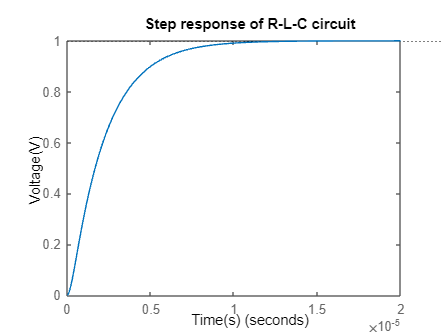

Vin = ones(size(t));
step(g1, t);
title('Step response of R-L-C circuit' )
xlabel ('Time(s)');
ylabel('Voltage(V)');


%when voltage step is applied the inductor does not change
%instantaniuslydue to prescence of inductor which resists the current
%eventuly it reaches a steady state when it is equal to the input voltage

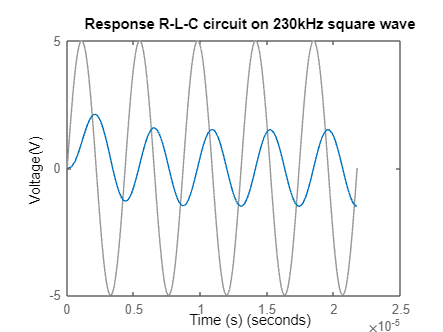

%230kHz

%it does not have enough to reach 5v volts due to the frquency being too
%high thus making a sawtooth. the grey line is what it should be and the
%blue is the actual result produced 
figure;
f = 230000;
t = 5*(linspace(0, 1/f, 1000)) ;
Vin = 5*(sin(2*pi*f*t));
lsim(g1, Vin, t);
title('Response R-L-C circuit on 230kHz square wave')
xlabel ('Time (s)')
ylabel('Voltage(V)')

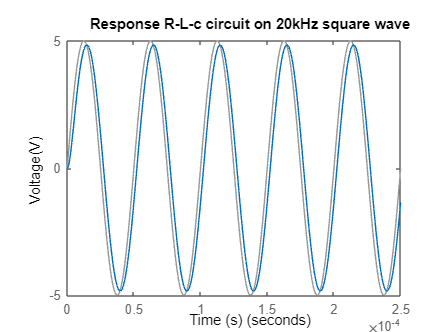

%20kHz
%as you can see the two lines are perfectly in sync this is due to the
%frequency being low enough so that it reaches 5v without getting cut off
%from repeating itself 
figure;
f = 20000;
t = 5*(linspace(0, 1/f, 1000)) ;
Vin = 5*(sin(2*pi*f*t));
lsim(g1, Vin, t);
title('Response R-L-c circuit on 20kHz square wave')
xlabel ('Time (s)')
ylabel('Voltage(V)')

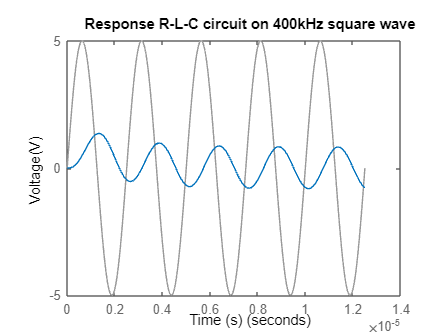

%400kHz
%the results are out of sync due to the frequency being too high again thus
%meaning it keeps repeating itself without reaching the final value of 5v
figure;
f = 400000;
t = 5*(linspace(0, 1/f, 1000)) ;
Vin = 5*(sin(2*pi*f*t));
lsim(g1, Vin, t);
title('Response R-L-C circuit on 400kHz square wave')
xlabel ('Time (s)')
ylabel('Voltage(V)')